# DSP Special Assignment 

## Topic - Basis Pursuit Denoising

## 20BEC130 & 20BEC137

clc;
close all;
clear all;

### Speech Signal Generation and Plot

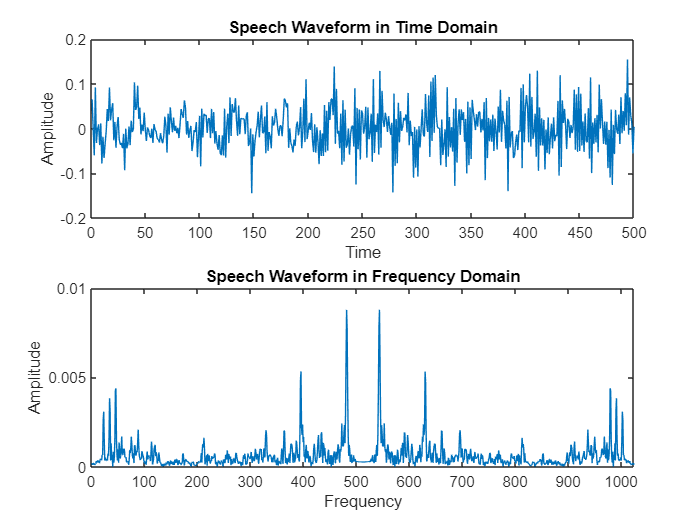


[sp1, fs] = audioread('D:\SEM 5\DSP LAB\Special Assignment\file_example_WAV_1MG.wav');
M = 500; % M : length of signal
s = sp1(5500+(1:M)); % s : signal (without noise)

% Plotting the speech Signal in Time Domain

figure(1)
subplot(2,1,1)
plot(s)
ylabel('Amplitude');
xlabel('Time');
title('Speech Waveform in Time Domain')

% Plotting the speech Signal in Frequency Domain

Y = (1/1024)*fft(s,1024);
figure(1)
subplot(2,1,2)
plot(abs(Y))
xlim([0 1024])
ylabel('Amplitude');
xlabel('Frequency');
title('Speech Waveform in Frequency Domain')

### Noisy Signal Generation and Plot

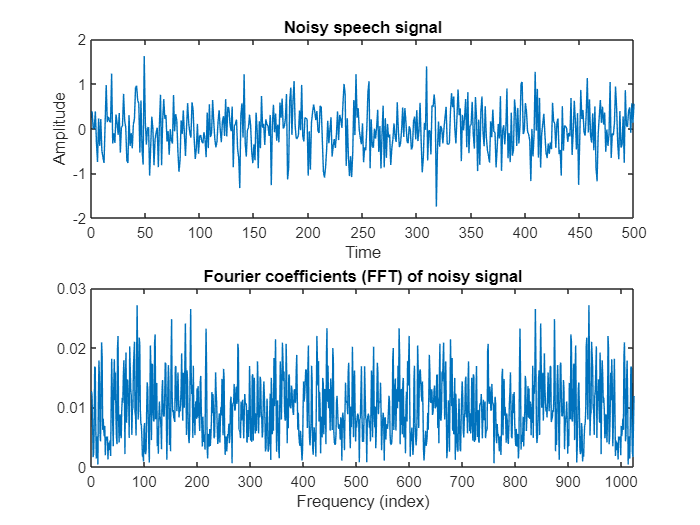


w = 0.5*randn(size(s));    % w : zero-mean Gaussian noise
y = s + w;                 % y : Adding noise to speech signal

% Plotting the noisy Signal in Time Domain

figure(2)
subplot(2,1,1)
plot(y)
title('Noisy speech signal')
ylabel('Amplitude');
xlabel('Time');

% Plotting the noisy Signal in Frequency Domain

N = 2^10;                   % N : Length of Fourier coefficient vector
Y = (1/N)*fft(y,N);         % Y : Spectrum of noisy signal

figure(2)
subplot(2,1,2)
plot(abs(Y))
xlim([0 1024])
title('Fourier coefficients (FFT) of noisy signal');
xlabel('Frequency (index)')

### BPD Algorithm


[A, AH] = MakeTransforms('DFT', 500, 2^10)

Reconstruction error = 0.000000
Energy ratio = 1.000000


A = function_handle with value:
    @(X)truncate(ifft(X),N)*sqrt(Nfft)


AH = function_handle with value:
    @(x)fft(x,Nfft)/sqrt(Nfft)


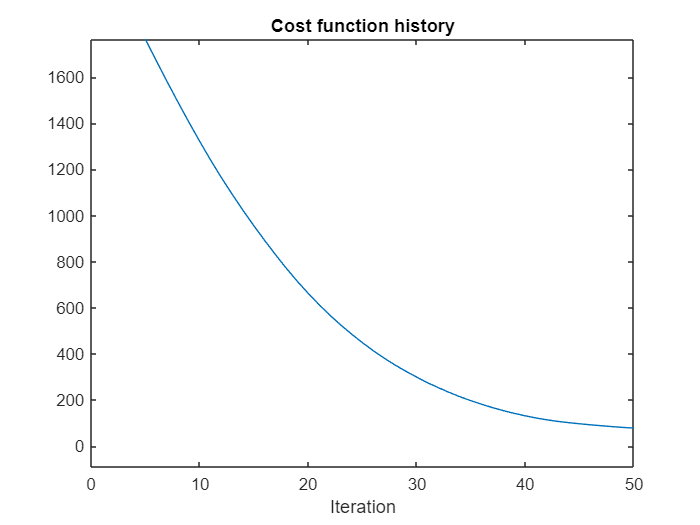


% Defining algorithm parameters

lambda = 7; % lambda : regularization parameter
Nit = 50; % Nit : number of iterations
mu = 500; % mu : ADMM parameter

% Running the  BPD algorithm

[c, cost] = BPD(y, A, AH, lambda, mu, Nit);

figure(4)
plot(cost)
title('Cost function history');
xlabel('Iteration')
it1 = 5;
del = cost(it1) - min(cost);
ylim([min(cost)-0.1*del cost(it1)])
xlim([0 Nit])

### Denoising using BPD

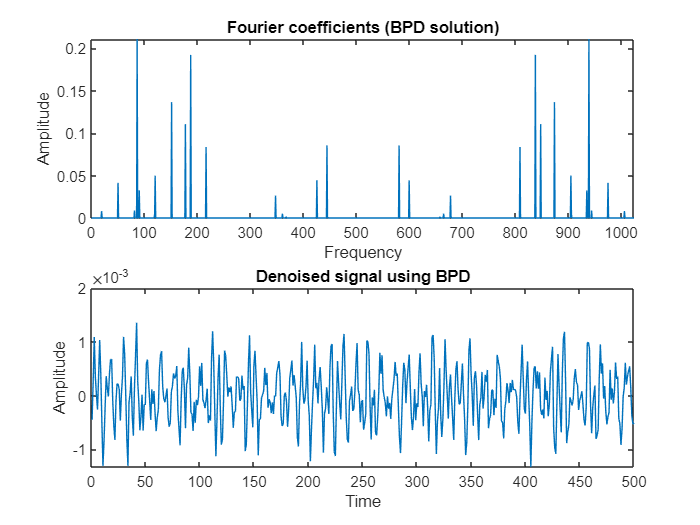


% Plotting the denoised Signal in Frequency Domain

figure(5)
subplot(2,1,1)
plot(abs(c))
xlim([0 1024])
title('Fourier coefficients (BPD solution)');
ylabel('Amplitude')
xlabel('Frequency')


% Plotting the denoised Signal in Time Domain

figure(5)
subplot(2,1,2)
plot(ifft(c))
xlim([0 500])
title('Denoised signal using BPD');
ylabel('Amplitude')
xlabel('Time')